% Hyperspectral Imaging and Visualization Script
% ------------------------------------------------
% This script is designed to process video data from a hyperspectral imaging setup
% involving the recording of dynamic scenes, specifically focused on biomedical applications
% such as ischemic and non-ischemic finger diagnosis. The video 'rachaelfinger4.avi' is
% used as a primary data source.
%
% The objective is to convert this video into a hypercube (a 3D array where two dimensions
% are spatial and the third is spectral) using two distinct sampling methods outlined as 
% Method 1 and Method 2. This hypercube is then used to perform spectral analysis and
% visualization techniques to inspect and analyze the spectral properties of different regions.
%
% Requirements:
% - MATLAB (R2019a or later recommended)
% - Image Processing Toolbox
% - Parallel Computing Toolbox
%
% The script includes:
% - Video reading and frame sampling
% - RGB to grayscale conversion specifically extracting the Y component
% - Spatial resizing and normalization of video frames
% - Generation of hypercubes for spectral analysis
% - Visualization of spectral data through plots and surface plots
%
% The script is structured to be modular and easily adaptable for different videos and
% analysis needs. Parallel processing capabilities are employed to expedite the processing
% of video data. Ensure that the required toolboxes are installed and that the video file
% path is correctly set up before running this script.



clc,close,clear all
addpath('Finger Videos\')

% Initialise videoreader object
vid = VideoReader('rachaelfinger4.avi');


% Ensure Parallel Computing Toolbox is available
if ~license('test', 'Distrib_Computing_Toolbox')
    error('Parallel Computing Toolbox is not available.');
end

% Method 1: sample the video frame by frame. Recommended to use METHOD 2
% vid.CurrentTime = 0;
% idx = 1
% 
% % set number of frames to extract
% hheight = size(y_frame, 1);
% hlength = size(y_frame, 2);
% n_frames = hheight;
% vidcube = zeros(hheight, n_frames, hlength);
% 
% 
% % dump video frames into a datacube
% while vid.hasFrame() && idx <= n_frames
%     temp_frame = vid.readFrame();
%     y_temp_frame = rgb2y(temp_frame);
%     y_temp_frame = imresize(y_temp_frame, 0.25);
%     y_temp_frame_norm = y_temp_frame / 255;
%     % vidcube(idx, :, :, :) = temp_frame;
% 
%     % create video datacube (3d array)
%     vidcube(:,idx,:) = y_temp_frame_norm;
%     idx = idx + 1;
% end
% 


% Method 2: sample the video using total frames and duration

% Initialization and setup
vid.CurrentTime = 0; % Start at the beginning of the video
vid_total_time = vid.Duration; 
% vid_total_frames = vid.NumFrames; 
n_frames = 900; % Number of frames to extract, set to 'height' as per your code

% Calculate interval for sampling frames based on total time and number of frames to extract
time_interval = vid_total_time / n_frames;

% Determine size of spectrogram using a sample frame
sample_frame = readFrame(vid);
sample_frame_resized = imresize(sample_frame, 0.25);
[hheight, hlength, ~] = size(sample_frame_resized);
vid.CurrentTime = 0; % reset

% Initialize the hypercube on the GPU
vidcube = gpuArray.zeros(hheight, n_frames, hlength, 'single');

% Sample frames at regular intervals
for i = 1:n_frames
    % Calculate and set the current time for the video to the next sample point
    vid.CurrentTime = (i-1) * time_interval;
    
    % Read and process the frame if available
    if vid.hasFrame()
        temp_frame = vid.readFrame();

        temp_frame = gpuArray(temp_frame);

        y_temp_frame = rgb2y(temp_frame); % Convert to Y component
        y_temp_frame = imresize(y_temp_frame, 0.25); % Resize the frame
        y_temp_frame_norm = y_temp_frame / 255; % Normalize the frame
        
        % Store the processed frame into the hypercube
        vidcube(:, i, :) = y_temp_frame_norm;
    end
end

vidcube = gather(vidcube); % THIS IS THE HYPERCUBE



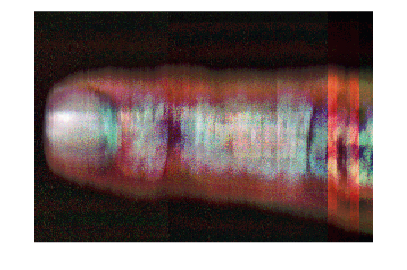

isc_hcube = struct with fields:
    vidcube: [612×900×816 double]


non_isc_hcube = struct with fields:
    vidcube: [612×900×816 single]


%% Reconstructing the hyperspectral image through hypercube
wavelength = linspace(0.3, 1.0, 816); % calibrate this
hcube = hypercube(non_isc_hcube.vidcube, wavelength);
img = colorize(hcube,'Method', 'rgb', 'ContrastStretching', true);

figure
imshow(img)

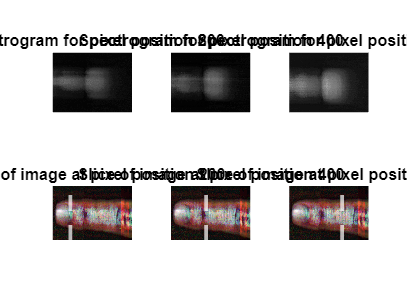

pixel_position = 200

pixel_position = 400

pixel_position = 600

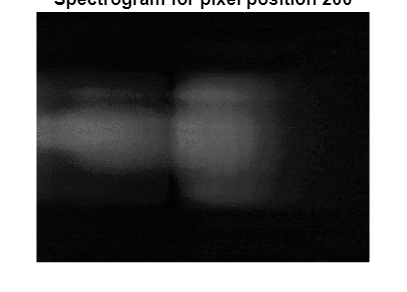

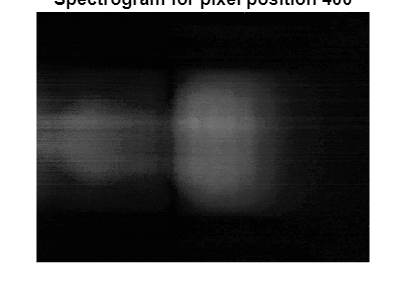

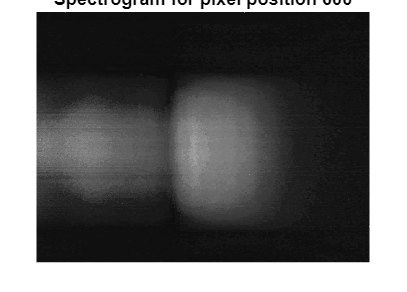

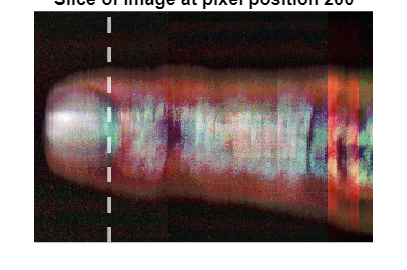

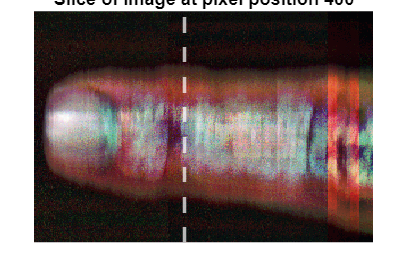

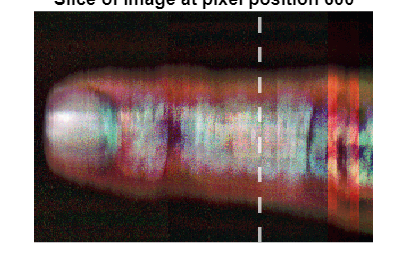

% Get sample slices of the hypercube and the corresponding spectrogram
figure
t = tiledlayout(2,3,'TileSpacing','tight');
pixel_positions = [200, 400, 600];
for i = 1:3
    pixel_position = pixel_positions(i);
    nexttile
    imshow(squeeze(non_isc_hcube.vidcube(:, pixel_position,:)), []);
    title(['Spectrogram for pixel position ', num2str(pixel_position)])
end
for j = 1:3
    pixel_position = pixel_positions(j)
    nexttile
    imshow(img); hold on;
    % Draw a line at 'pixel_position' with specific properties
    xline(pixel_position, 'Color', 'w', 'LineWidth', 2, 'LineStyle', '--');
    title(['Slice of image at pixel position ', num2str(pixel_position)])
end

% Illustrate the hypercube
M = zeros(size(vidcube,1), size(vidcube,3),10);
positions = ceil(linspace(1,size(vidcube,2),10));

% Slice the hypercube and save it in array M 
for j = 1:10
    spectrogram = squeeze(vidcube(:,positions(j),:));
    M(:,:,j) = spectrogram;
end

figure ; hold on

% Define the base Y position and the interval between slices
baseYPosition = 0;
yInterval = 100;

colormap gray;

% Loop through each slice in M to plot them
for j = 1:size(M,3)
    slice = M(:,:,j); 
    [X, Z] = meshgrid(1:size(M,2), 1:size(M,1));
    
    % Adjust Y coordinates for the current slice's position
    Y = baseYPosition + (j-1) * yInterval * ones(size(slice));
    
    % Flip the slice in the Z dimension to display it correctly
    sliceFlipped = flipud(slice);
    
    surf(X, Y, Z, double(sliceFlipped), 'FaceColor', 'texturemap', 'EdgeColor', 'none', 'CDataMapping', 'scaled');
   
end


clim([0 0.2]);

% Plot the image
[height, width, ~] = size(img);

% Create Y and Z coordinates for the image
[Y, Z] = meshgrid(1:width, 1:height);

% Create X coordinates (all zeros to plot at x=0)
X = zeros(size(Z));

imgFlipped = flipud(img);
surf(X, Y, Z, imgFlipped, 'FaceColor', 'texturemap', 'EdgeColor', 'none');

axis off
title('Hypercube Visualisation')



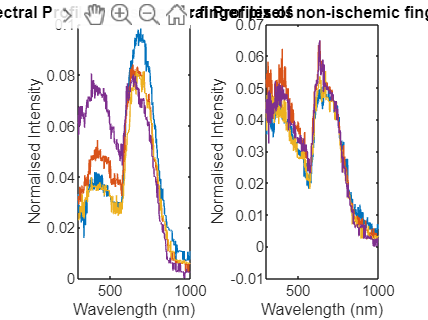

% Plot spectral profiles

wavelength = linspace(300, 1000, 816);
figure

subplot(121)
plot(wavelength, Signature1); hold on
plot(wavelength, Signature2);
plot(wavelength, Signature3);
plot(wavelength, Signature4); hold off
xlim([300 1000])
ylim([0 0.1])
xlabel('Wavelength (nm)')
ylabel('Normalised Intensity')
title('Spectral Profiles of ischemic finger pixels')

subplot(122)
plot(wavelength, Signature11); hold on
plot(wavelength, Signature21);
plot(wavelength, Signature31);
plot(wavelength, Signature41); hold off
xlim([300 1000])
ylim([0 0.1])
xlabel('Wavelength (nm)')
ylabel('Normalised Intensity')
title('Spectral Profiles of non-ischemic finger pixels')

function Y = rgb2y(RGB)
    % Transformation matrix to get Y component
    transformMat = [0.299, 0.587, 0.114];
    % Apply the matrix to each pixel
    Y = double(RGB(:,:,1)) * transformMat(1) + double(RGB(:,:,2)) * transformMat(2) + double(RGB(:,:,3)) * transformMat(3);
end